# They Sent Men on the Moon

[⇦ Overview](matlab:open('./Overview.m'))

Conservation of Mass and Momentum are the fundamental equation of fluid dynamics. This script investigates their application to the modeling of the launch of one of the most famous space exploration missions, comparing the results to the actual flight log from the mission.

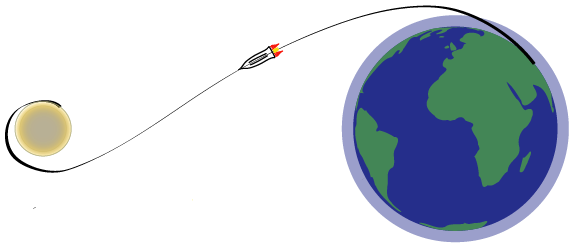

  **Try**. Please, fill in your name in the following field:

StudentName = "Valentin Boutrouche ";

**Before you get started:**

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon  at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://www.mathworks.com/learn/tutorials/matlab-onramp.html), a free 2 hour online tutorial that teaches the essentials of MATLAB.

The    and   icons refer to two different types of interactive activities that you will find in this script. The first one is usually designed to explore the visualization of some of the concepts introduced in this script. The second one is designed to challenge your understanding of those concepts and can be used for grading and completion checks by your professor.

## Introduction

From 1961 to 1972, NASA pursued the Apollo space exploration program. Named after the Greek god of the sun, the program’s principal objective was to establish the first human presence on the Moon. In 1969, the Apollo 11 mission launched a small spacecraft from Cape Canaveral, Florida. This groundbreaking mission successfully established the first human presence on the Moon. The rocket used for the launch, Saturn V, was and remained the rocket with the largest payload capacity. In this module, we are applying the mass conservation and momentum conservation equation to study the first phase of the Saturn V launch. This phase represents the first 160 seconds of the flight, during which the rocket is propelled with the five F-1 rocket engines of the rocket’s first stage.

  **Try**. Comparing the size of Saturn V with a football field.

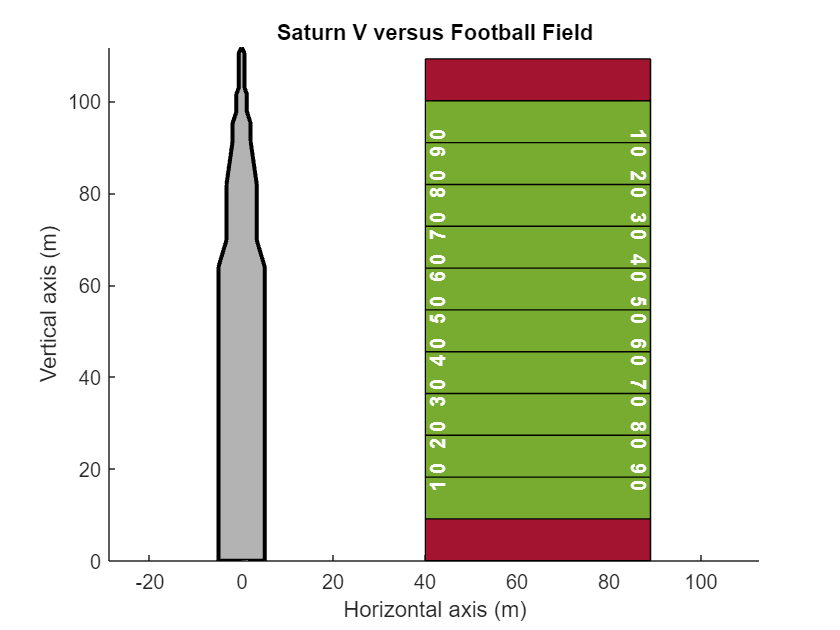

IntroRocket(); 

## A First Model of The Launch

In this part of the script, we are utilizing the integral form of the mass and momentum conservation equation to define the rocket’s altitude with respect to time during the first phase of the launch. For this model, we are making the following assumption:

- The friction forces along the hull of the rocket are negligible.

- The rocket is flying purely vertically.

Solving the mass and conservation equation's integral form presents many opportunities for sign and integration mistakes. Deriving these equations carefully, with a precise sequence of steps, is usually the best way to avoid these traps.

### Define Control Volume

The first step consists of carefully defining the problem's Control Volume (CV) and Control Surfaces (CS) of the problem.

  **Try**. Use the following drop-down control to visualize the Control Volume and Control Surfaces.

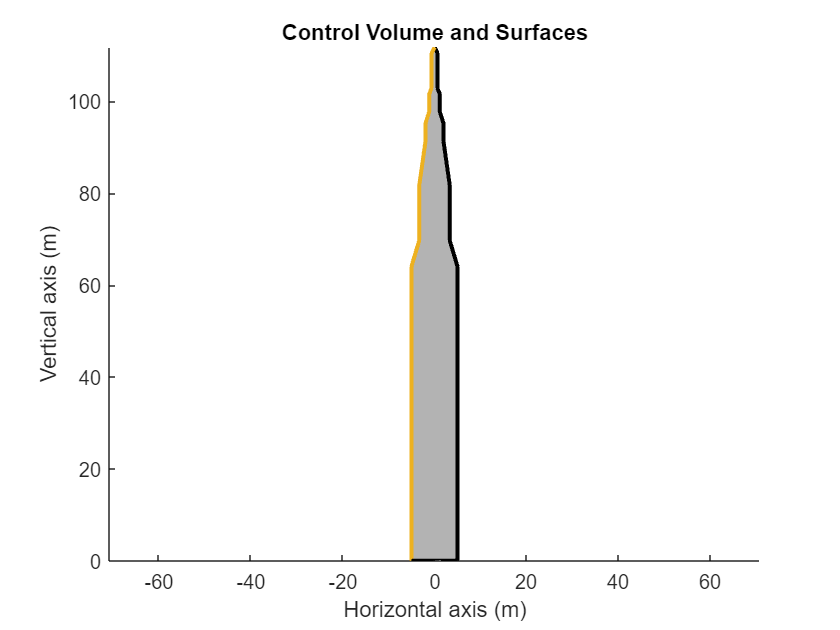

IntroControlVolume("CSL");

Solving the mass and conservation equation necessarily involves the integration of mass and momentum fluxes through the control surfaces. This step is prone to sign error because coming from the scalar product of the fluxes (vector) with the normal vector of the Control Surface (vector).


$$\int_{CS} {\bf Flux}\cdot {\bf NormalVector} \text{ } dS$$


By convention, we want the resultant of this integration to be positive if the flux goes into the Control Volume and negative if the flux is going out of the Control Volume.

 **Exercise.** What direction should the normal vector of the bottom Control Surface be to obey this convention?

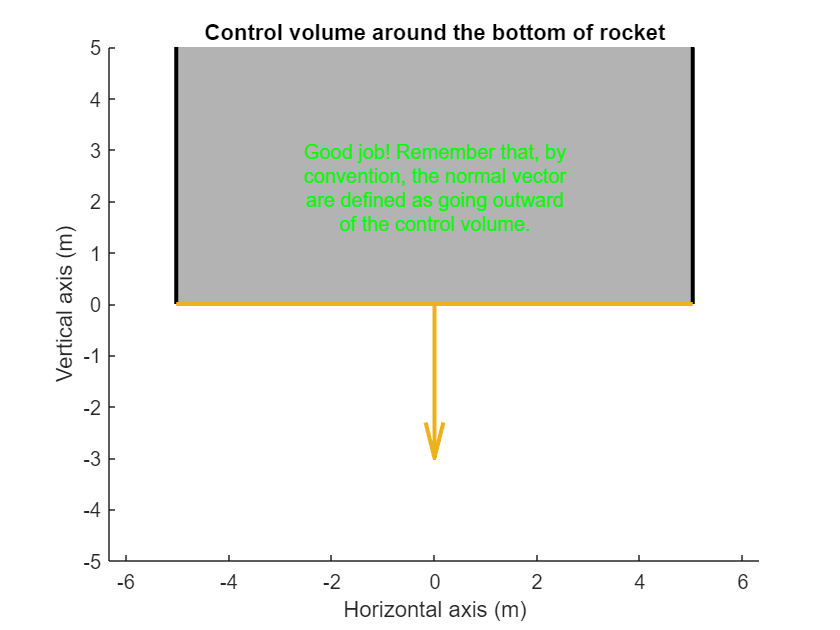

SelectDirectionBottomControlSurface("Downward");

  **Try**. Use the following drop-down control to visualize the normal vector to the other Control Surfaces.

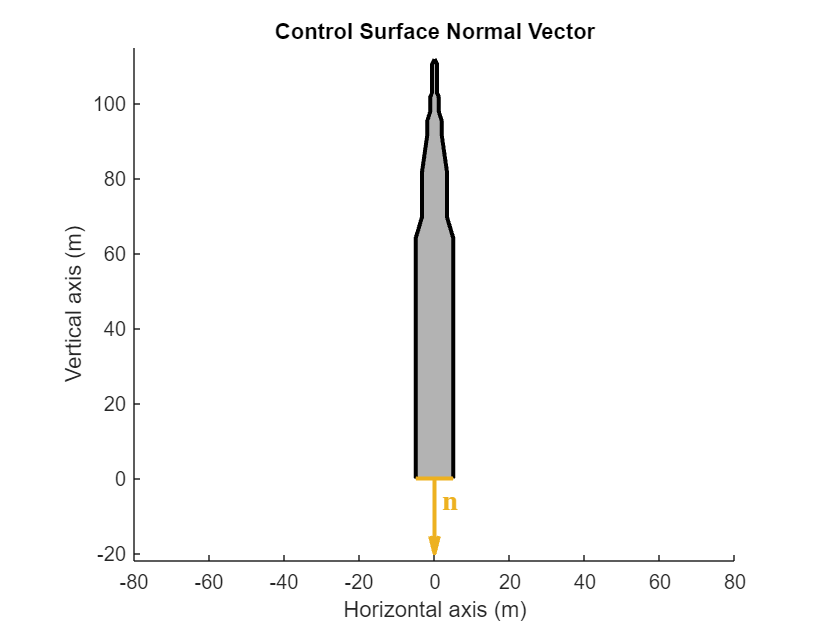

LookAtNormalVector("CSB");

  **Pro-tip**. Formally taking note of the normal to the Control Surface early in the problem can help avoid error signs later in the derivation.

### Appling The Mass Conservation Equation

Now that the Control Volume and Control Surfaces were carefully defined, as well as their normal vector. We can start solving the conservation equation. The mass conservation equation is recommended to be solved first because its constituting terms are usually more straightforward than the term present in the momentum and energy conservation equation. 

** Demonstration**. The integral term over the Control Surfaces can be easily broken down.


$$\frac{\partial}{\partial t}\int_{CV}\rho dV+\int_{CS} ({\bf u}\cdot{\bf n})\rho dS = \underbrace{\frac{\partial}{\partial t}\int_{CV}\rho dV}_\text{A}
+
\underbrace{\int_{CS_{right}} ({\bf u}\cdot{\bf n})\rho dS }_\text{B}
+
\underbrace{\int_{CS_{left}} ({\bf u}\cdot{\bf n})\rho dS }_\text{C}
+
\underbrace{\int_{CS_{bottom}} ({\bf u}\cdot{\bf n})\rho dS }_\text{D}
= 0$$


  **Pro-tip. **In most cases, some terms in the equation are equal to zero. Identifying those before solving each integral is an excellent way to simplify the problem and avoid mistakes.

 **Exercise.** Identify the term equal to zero in the previous equation.

CheckNullTermMassConservation(A = false, B = true, C = true, D = false);  

Good job! You indentified all of the null term in the mass conservation equation.


Now that the equation has been simplified as much as possible, we can start the integration process, term by term.

 **Exercise.** What is term A equal to?


$$\text{1) } \frac{\partial m(t)}{\partial t} 
\quad\quad
\text{2) } {\bf u}\cdot \frac{\partial m(t)}{\partial t}
\quad \quad
\text{3) } u_e \frac{\partial m(t)}{\partial t}
\quad \quad
\text{4) } \frac{\partial m(t)\times t}{\partial t}$$


CheckFirstTermMassConservation(0);

The remaining term integration over the Control Surface involves the dot product of the velocity with the Control Surface normal vector.

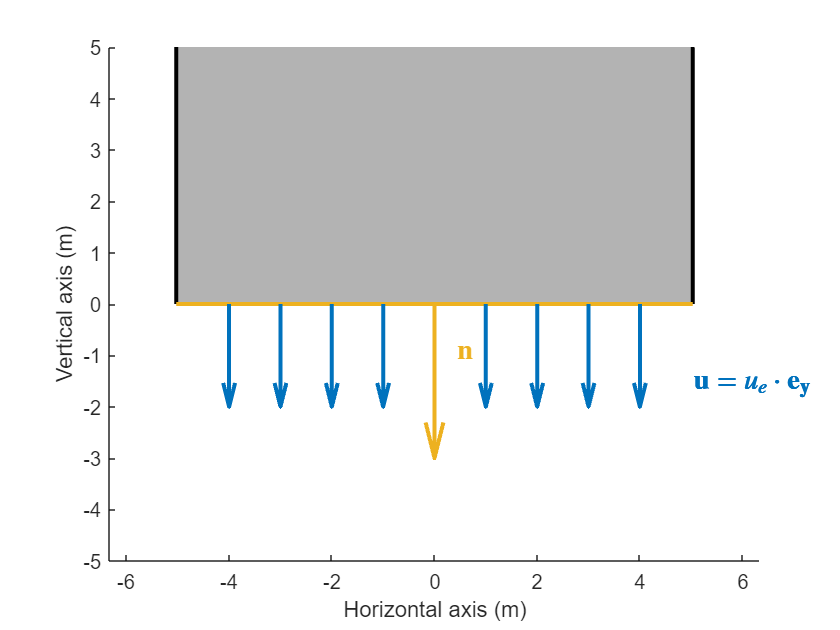

figure()
DrawSaturn(Highlight="CSB", ZoomIn=true, NormalVector=true, DrawExhaustVelocity=true, WriteExhaustVelocity=true);

 **Exercise. **What does this dot product equate to on the bottom Control Surface?


$$\text{1) }{\bf u}\cdot{\bf n} = -u_e
\quad\quad
\text{2) }{\bf u}\cdot{\bf n} = u_e$$


CheckNormalDotVelocity(0);

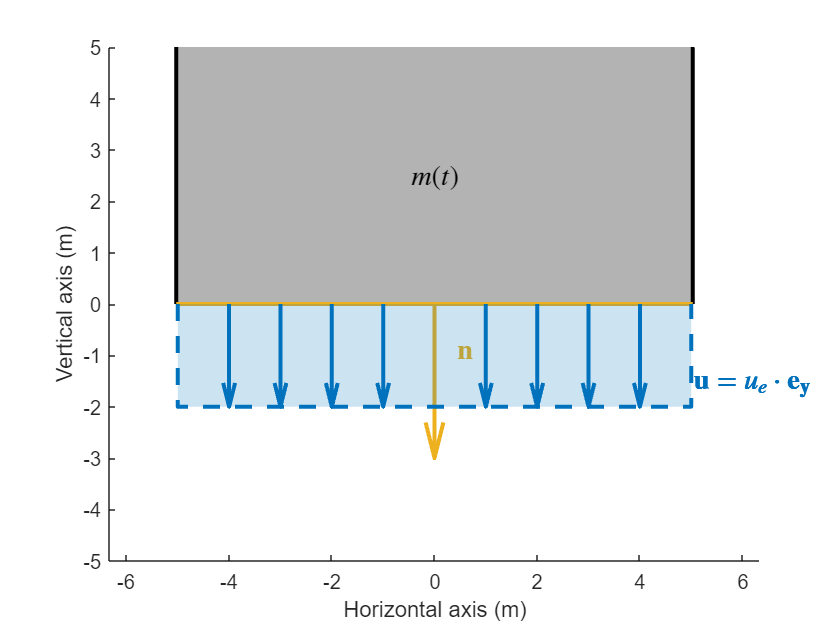

figure()
DrawSaturn( ZoomIn=true, Highlight="CSB", NormalVector=true, DrawExhaustVelocity=true, ...
    WriteExhaustVelocity=true, DrawExhaustMassFlow=true, WriteMass=true );

In the previous figure, the highlighted area represent the value of the remaining integral in the Mass Conservation equation:


$$\frac{\partial m(t)}{\partial t}
+\int_{CS_{bottom}} \rho u_e dS
= 0$$


 **Exercise** What is the value of the remaining integral in equation (XXX)?


$$\text{1) } {\bf u}\cdot\dot{m_e}
\quad\quad
\text{2) } -u_e\dot{m_e} 
\quad\quad
\text{3) } \dot{m_e}
$$


CheckRemainingTermMassConservation(3)

Good job! The remaining term in the mass conservation equation represent the mass flow leaving the Control Volume through the bottom Control Surface.


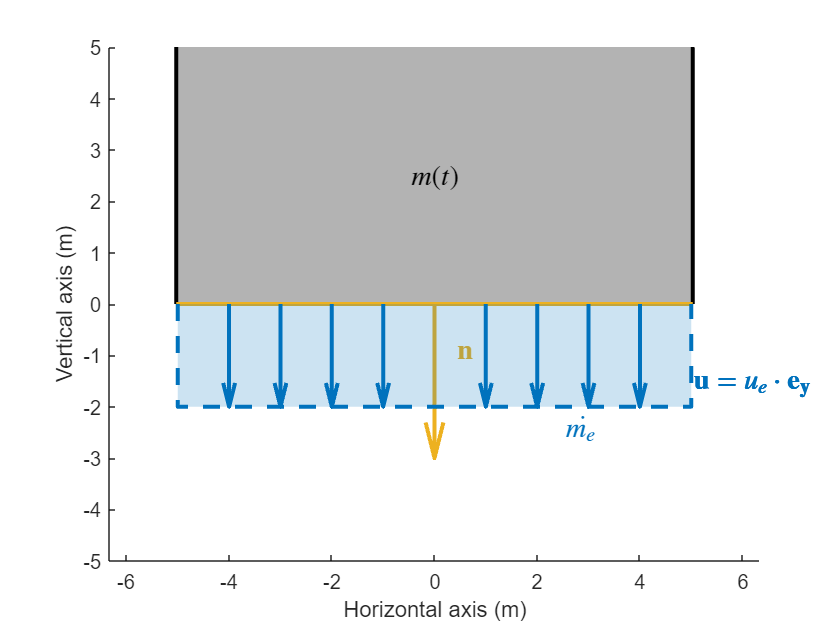

figure()
DrawSaturn(ZoomIn=true, Highligh="CSB", NormalVector=true, DrawExhaustVelocity=true, WriteExhaustVelocity=true, ...
    DrawExhaustMassFlow=true, WriteExhaustMassFlow=true, WriteMass=true);

The final differential equation obtained from the mass conservation equation is the following: 


$$\frac{\partial m(t)}{\partial t} = -\dot{m_e}$$


The solution of the differential is of the form: $m(t) = -\dot{m_e}   t + C$

We can define a value of the constant integration $C$by considering the initial mass of the rocket $m_0$ at $t = 0
$.


$$m(t) = m_0 - \dot{m_e}t$$


In the case of the Saturn V rocket for the Apollo 11 mission, the initial mass of the rocket was 2,950,000 kg and the total mass flow out of the five F-1 engine totaled at 12,600 kg/s.

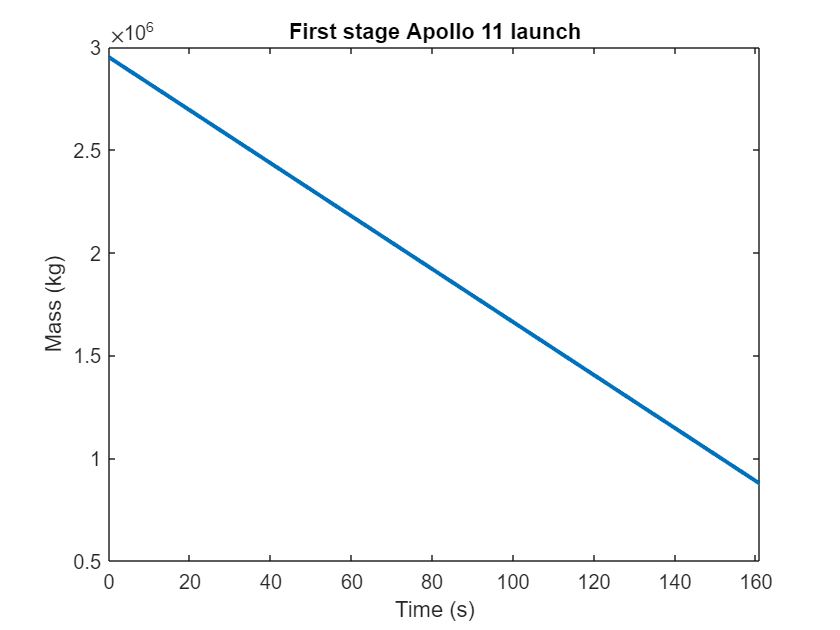

 
SolveMassConservationEquation();

 **Reflect**. The amount of rocket fuel used during the first phase of the launch represent emptying 200 regular car tank every second during the 161 seconds of the first phase, almost 34,000 cars. 

### Apply Conservation of Momentum

XXX Comment about Mass conservation equation

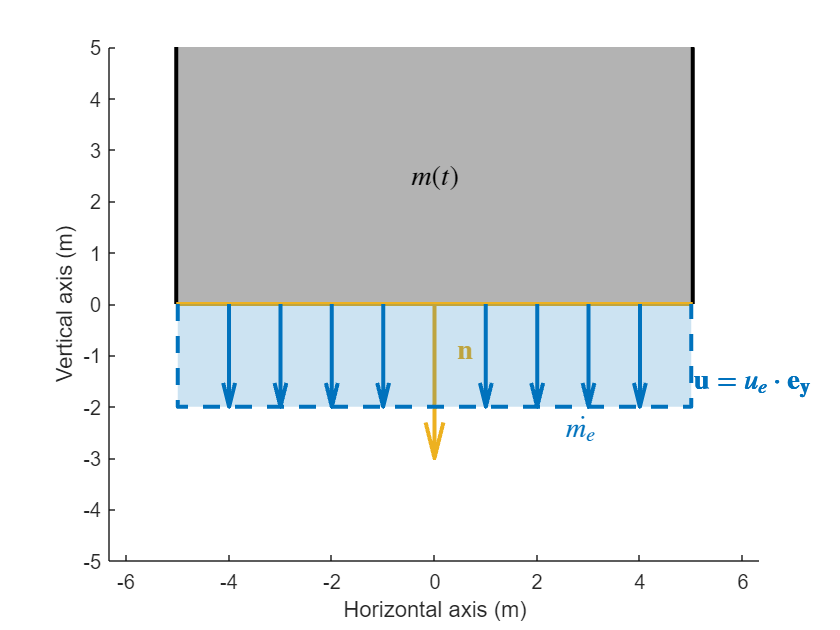

figure()
DrawSaturn(ZoomIn=true, Highligh="CSB", NormalVector=true, DrawExhaustVelocity=true, WriteExhaustVelocity=true, ...
    DrawExhaustMassFlow=true, WriteExhaustMassFlow=true, WriteMass=true);

The Mass Flux exiting the rocket engine is generating the force that is setting the rocket in motion.

  **Try**. What is the direction of the thrust force applied on the rocket?

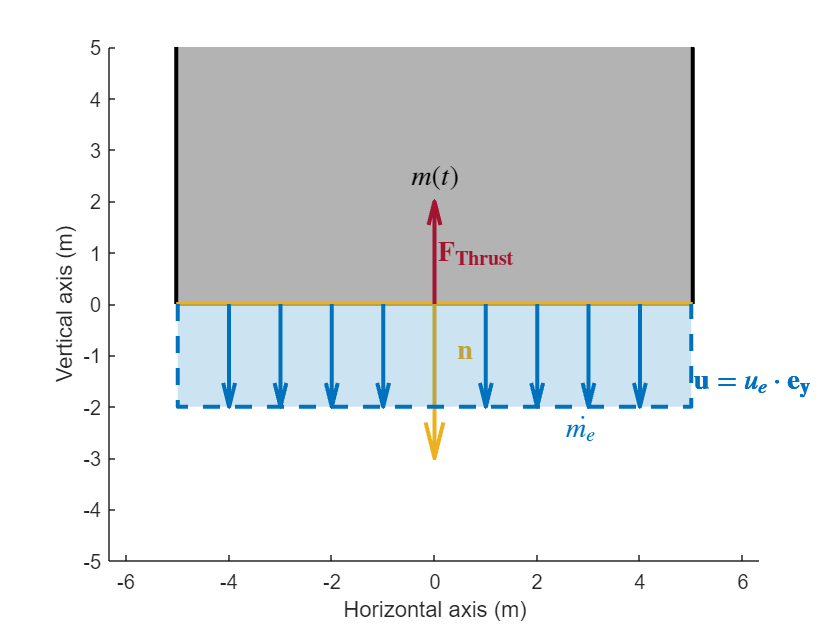

CheckThrustDirection( "Upward");

The Momentum Conservation equation is usually expressed as follow:


$$\underbrace{\frac{\partial}{\partial t}\int_{CV}\rho{\bf u}dV}_\text{Acceleration}
+
\underbrace{\int_{CS}({\bf u}\cdot{\bf n})\rho{\bf u}dS}_\text{Thrust}
=
\Sigma {\bf F}$$


#### Derivation of the Acceleration Term

First, we should integration the acceleration term in XXX

  **Pro-tip**. All of the velocity are considered with respect to the moving reference frame that is our Control Volume.

  **Pro-tip**. In order to consider this equation (XXX) for an accelerating Control Volume, we includes the acceleration of the control Volume as a forces acting on the Control Volume.

  **Try**. What is the direction of the resulting force acting on the Control Volume?

Good job! Resulting forces are always directed in the opposite direction of their sources.


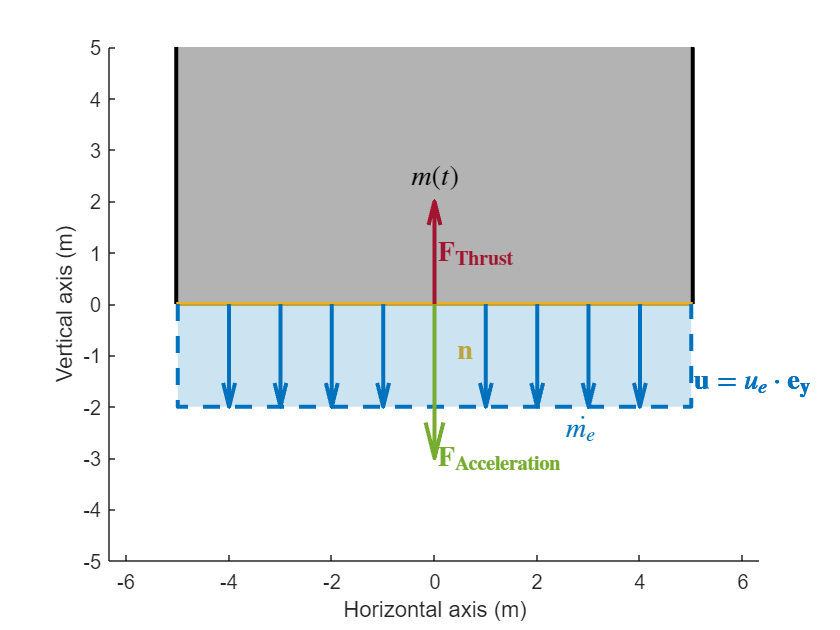

CheckAccelerationResultantControlVolume("Downward");

#### Body Forces identification


$$\underbrace{\frac{\partial}{\partial t}\int_{CV}\rho{\bf u}dV}_\text{Acceleration}
+
\underbrace{\int_{CS}({\bf u}\cdot{\bf n})\rho{\bf u}dS}_\text{Thrust}
=
\Sigma {\bf F}$$


Blah Blah Blah, the term $\Sigma{\bf F}$ represents the sum of the body forces applied to the Control Volume.

  **Activity.** What forces should be included in the body force term in the momentum conservation equation?

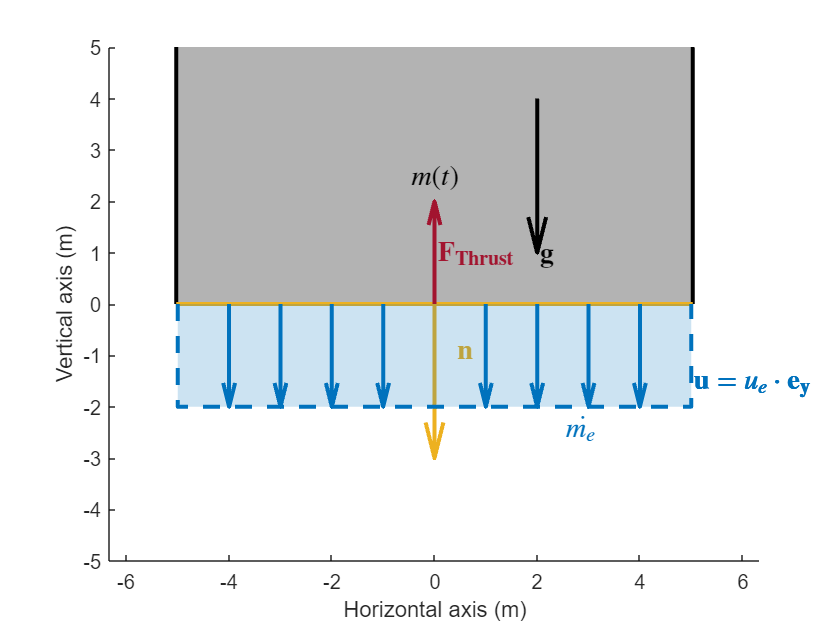

 
CheckAppliedForces( Gravity = true, ...
                    Spring = false, ...
                    Electric = false, ...
                    Friction = true, ...
                    Magnetic = false, ...
                    Thrust = false, ...
                    Acceleration = true);


$$\frac{\partial}{\partial t}\int_{CV}\rho{\bf u}dV
+
\int_{CS}({\bf u}\cdot{\bf n})\rho{\bf u}dS
=
m(t){\bf g} - m(t){\bf a_{CV}}$$


We can XXX the equation along the vertical axis:


$$\frac{\partial}{\partial t}\int_{CV}\rho({\bf u}\cdot{\bf e_y})dV
+
\int_{CS}({\bf u}\cdot{\bf n})\rho({\bf u}\cdot{\bf e_y})dS
=
m(t){\bf g}\cdot{\bf e_y} - m(t){\bf a_{CV}}\cdot{\bf e_y}$$



$$\frac{\partial}{\partial t}\int_{CV}\rho({\bf u}\cdot{\bf e_y})dV
+
\int_{CS}({\bf u}\cdot{\bf n})\rho({\bf u}\cdot{\bf e_y})dS
=
-m(t)g - m(t)\frac{\partial^2 y_\text{CV}}{\partial y^2}$$


We already know the definition of $m(t)$ from applying the Mass Conservation equation to the Control Volume. The gravity $g$ is considered constant equal to 9.81 $\text{m/s}^2$. The altitude of the Control Volume is equivalent to the altidue of the rocket and is actuall what we are looking to define here.

**Assumption: **The acceleration term due to mass flow inside the Control Volume is neglected. It assume that this term is negligible compare to the thrust generated by the rocket.

Therefore, the last term to consider here is the integral thrust term.

#### Derivation of the Thrust Term

Just like we did for the Mass Conservation equation, we are breaking down the integral over the Control Surfaces over three integral over each of the Control Surfaces:


$$\int_{CS}({\bf u}\cdot{\bf n})\rho({\bf u}\cdot{\bf e_y})dS
=
\int_{CS_\text{right}}({\bf u}\cdot{\bf n})\rho({\bf u}\cdot{\bf e_y})dS
+
\int_{CS_\text{left}}({\bf u}\cdot{\bf n})\rho({\bf u}\cdot{\bf e_y})dS
+
\int_{CS_\text{bottom}}({\bf u}\cdot{\bf n})\rho({\bf u}\cdot{\bf e_y})dS$$


  **Try**. Which integral term along the Control Surfaces is equal to zero?

Answer = [];
Answer(1) = true; 
Answer(2) = true; 
Answer(3) = false; 
 
CheckNullTermMomentumConservation(Answer);

Good job! You found all of the term equal to zero.


figure()
DrawSaturn(ZoomIn=true, Highlight="CSB", NormalVector=true, DrawExhaustVelocity=true, ...
                DrawExhaustMassFlow=true, WriteExhaustVelocity=true, WriteExhaustMassFlow=true, ...
                WriteMass=true, DrawThrust=true, DrawAcceleration=false, Gravity=true);


$$\int_{CS_\text{bottom}}({\bf u}\cdot{\bf n})\rho({\bf u}\cdot{\bf e_y})dS 
=
\int_{CS_\text{bottom}} (?) u_e \rho u_e dS
$$


  **Try**. What is the sign resulting from the two scalar product $(+)$ or $(-)
$?

CheckSignThrustTerm(2);

Good job!


  **Try**. Considering that the velocity along the bottom Control Surface is uniform, and the following results from the Mass Conservation $\int_{CV_\text{bottom}}\rho u_e dS = \dot{m_e}$, what is the final expression of the thrust term along the bottom Control Surface?

A) $u_e^2 \dot{m_e}$    B) $-u_e\dot{m_e}$     C) $-\dot{m_e}$    D) $-u_e^2$

Good job!


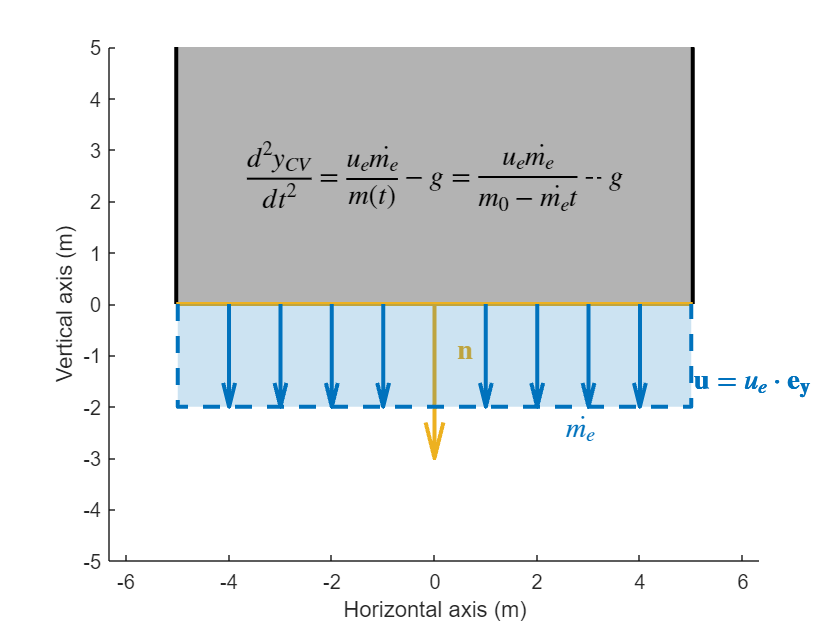

CheckThrustTerm("B");

## Comparing model to Apollo 11 flight log

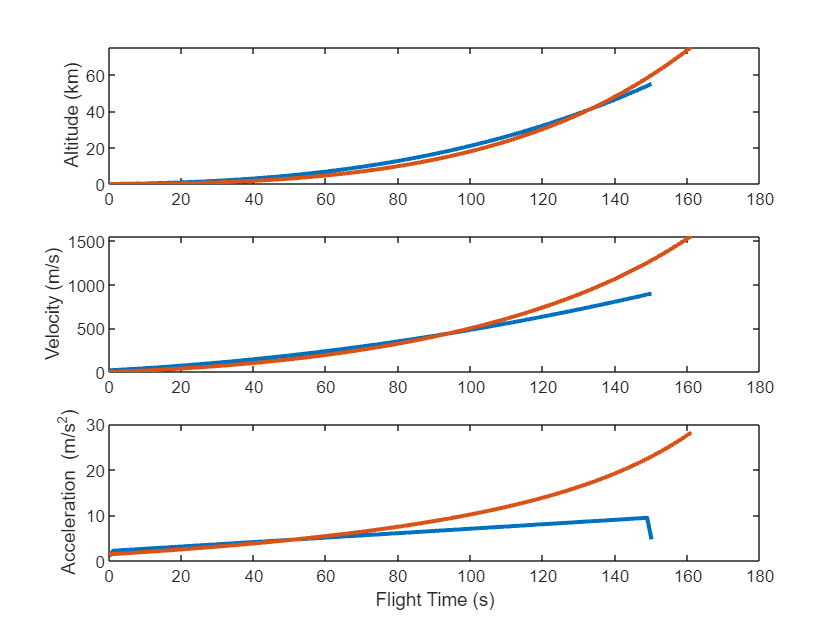

FirstModel();

 **Reflect**.  

## Causes of inacurracy

% WhatMakesFirstModelInacurrate(BadPhysics = false, ...
%                               Friction = false, ...
%                               FlightPath = false, ...
%                               Gravity = false, ...
%                               Performance = false)

### Frictions Forces

[Insert control volume image with friction forces]

### Non-vertical flight path

In the previous section, we consider that the trust of the rocket was directed verticaly and therefore the flight path of the rocket should be purely vertical. However, the flight path of Apollo 11 was not directed directly verticaly. The mission consisted a getting the spacecraft into earth orbit for a couple of revolution before the start the translunar injection.

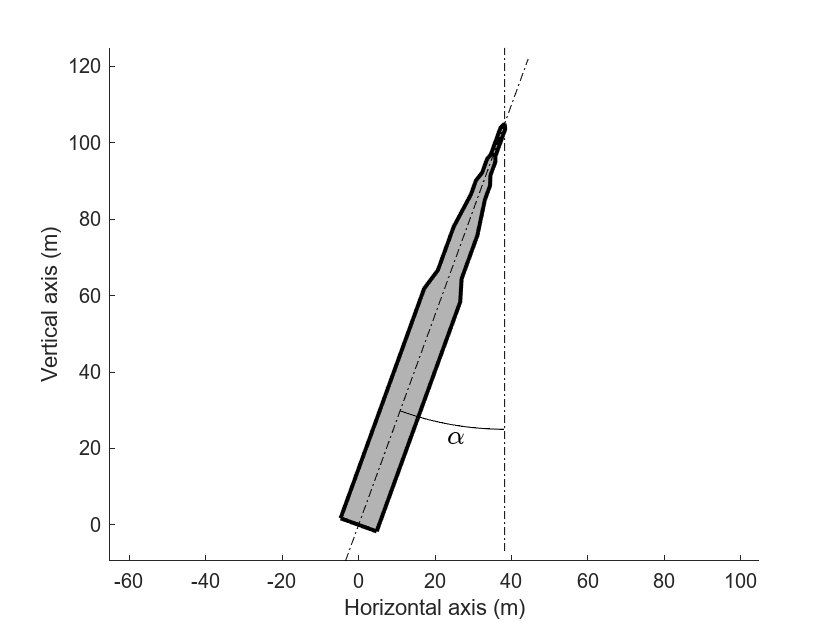

figure()
DrawSaturn(PathAngle=20);

Bla Blah Bla about the total trajectory

 
load Trajectory.mat
uif = uifigure();
gg = geoglobe(uif);
geoplot3(gg,Flight.Lat,Flight.Lon,Flight.El,'y','HeightReference','terrain', 'LineWidth',3)

## Improvement of the model

### **Correction for gravity**

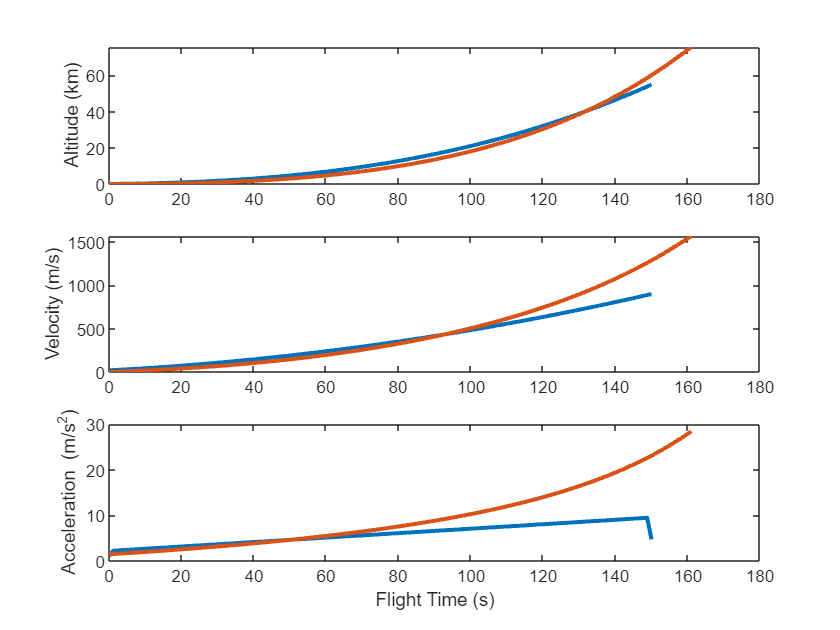

SecondModel();

### Correction for rocket flight path angle

Show back the ODE from the vertical climb:

Ask question about how the acceleration term is modify:


$$\frac{\partial^2y(t)}{\partial t^2}=cos(\alpha(t))\frac{\dot{m_e}u_e}{m_o-\dot{m_e}t} - g$$


Plot Angle of ascend

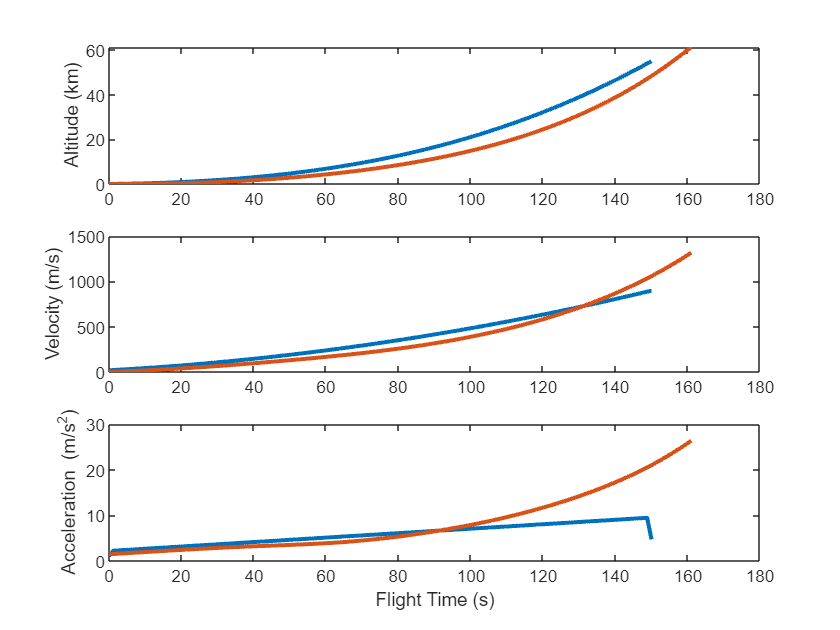

ThirdModel()

### Adding the friction forces

#### Wind tunnel experimentation of Saturn V aerodynamic

Talk about wind tunnel?

Identify the parameter of the problem?

What are the repeating parameter?

Define the Mach Number:

Define friction coefficient:

#### New ODE

#### Define the atmosphere surrounding the rocket

Question about the equation of fluid statics?

Question about the density?

Question about equation of state?

Final equation

Present the ISA, ICAO etc atmosphere

Show the function

#### Solve ODE with friction

## Conclusion

  **Pro-tip**. If your professore is requiring you to submit your completed script back, please make sure to add your name in the top of this file.

## Feedbacks

If you wish to provide feebacks to the developper, the developper provides three ways of reaching out:

- MATLAB File Exchange

- GitHub

- Email

If this script is used as an assigment by your professor and you wish to leave him feeback, you can add them to the following fieds, those feedbacks will stay in between you and your professor.

StudentFeedback = "This script was amazing";

## Helper Functions

If you wish to see the details of the code, select the **View** tab and switch to **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

function ax = DrawSaturn(opts)
    arguments
        opts.PathAngle (1,1) double = 0
        opts.DrawFootball (1,1) logical = false
        opts.Highlight (1,1) string {mustBeMember(opts.Highlight, ["none", "CV", "CSR", "CSL", "CSB"])} = "none"
        opts.NormalVector (1,1) logical = false
        opts.Gravity (1,1) logical = false
        opts.ZoomIn (1,1) logical = false
        opts.DrawExhaustVelocity (1,1) logical = false
        opts.DrawExhaustMassFlow (1,1) logical = false
        opts.WriteExhaustVelocity (1,1) logical = false
        opts.WriteExhaustMassFlow (1,1) logical = false
        opts.WriteMass (1,1) logical = false
        opts.DrawThrust (1,1) logical = false
        opts.DrawAcceleration (1,1) logical = false
        opts.WriteEquation (1,1) string = ""
    end

    % Define the axis:
    ax = axes;
    xlabel(ax, "Horizontal axis (m)")
    ylabel(ax, "Vertical axis (m)")
    axis equal
    hold on
    ColorHighlight = ax.ColorOrder(3,:);

    % Plot rocket:
    xR = [ 0 5.0292 5.0292 3.302 3.302 1.9558 1.9558 1.143 1.143 0.635 0.635 0];
    yR = [ 0 0 63.9826 69.7484 81.838 91.313 95.2246 97.7646 101.6 102.87 110.49 111.76];
    if opts.Highlight ~= "CV"
        patch( xR, yR, [0.7 0.7 0.7], "EdgeColor", "none")
        patch(-xR, yR, [0.7 0.7 0.7], "EdgeColor", "none")
    else
        patch( xR, yR, ColorHighlight, "EdgeColor", "none")
        patch(-xR, yR, ColorHighlight, "EdgeColor", "none")
    end

    % Right Control Surface
    if opts.Highlight ~= "CSR"
        line( xR(2:end),yR(2:end),"Color", [0 0 0], "LineStyle", "-", "LineWidth", 2)
    else
        line( xR(2:end),yR(2:end),"Color", ColorHighlight, "LineStyle", "-", "LineWidth", 2)
        if     opts.NormalVector 
            if opts.ZoomIn
                Pos = [xR(2) 2.0 0.0]';
                Dir = [3.0 0.0 0.0]';
            else
                Pos = [xR(2) 40.0 0.0]';
                Dir = [20.0 0.0 0.0]';
            end
            xy = rotz(-opts.PathAngle)*Pos;
            uv = rotz(-opts.PathAngle)*Dir;
            quiver(xy(1),xy(2),uv(1),uv(2), 0.0, AutoScale="off", LineWidth=2, Color=ColorHighlight, MaxHeadSize=0.7);
            text(xy(1)+0.5*uv(1)+0.2*norm(uv), xy(2)+0.5*uv(2)+0.2*norm(uv), "${\bf n}$", Interpreter="latex", ...
                HorizontalAlignment="center", Color=ColorHighlight, Rotation=-opts.PathAngle, FontSize=14)
        end
    end

    % Left Control Surface
    if opts.Highlight ~= "CSL"
        line( -xR(2:end),yR(2:end),"Color", [0 0 0], "LineStyle", "-", "LineWidth", 2)
    else
        line( -xR(2:end),yR(2:end),"Color", ColorHighlight, "LineStyle", "-", "LineWidth", 2)
        if     opts.NormalVector 
            if opts.ZoomIn
                Pos = [-xR(2) 2.0 0.0]';
                Dir = [-3.0 0.0 0.0]';
            else
                Pos = [-xR(2) 40.0 0.0]';
                Dir = [-20.0 0.0 0.0]';
            end
            xy = rotz(-opts.PathAngle)*Pos;
            uv = rotz(-opts.PathAngle)*Dir;
            quiver(xy(1),xy(2),uv(1),uv(2), 0.0, AutoScale="off", LineWidth=2, Color=ColorHighlight, MaxHeadSize=0.7);
            text(xy(1)+0.5*uv(1)+0.2*norm(uv), xy(2)+0.5*uv(2)+0.2*norm(uv), "${\bf n}$", Interpreter="latex", ...
                HorizontalAlignment="center", Color=ColorHighlight, Rotation=-opts.PathAngle, FontSize=14)
        end
    end

    % Bottom Control Surface
    if opts.Highlight ~= "CSB"
        line([-xR(2) xR(2)], [yR(2) yR(2)],"Color", [0 0 0], "LineStyle", "-", "LineWidth", 2)
    else
        line([-xR(2) xR(2)], [yR(2) yR(2)],"Color", ColorHighlight, "LineStyle", "-", "LineWidth", 2)
        if     opts.NormalVector 
            if opts.ZoomIn
                Pos = [0 0 0.0]';
                Dir = [0.0 -3 0.0]';
            else
                Pos = [0 0 0.0]';
                Dir = [0.0 -20 0.0]';
            end
            xy = rotz(-opts.PathAngle)*Pos;
            uv = rotz(-opts.PathAngle)*Dir;
            quiver(xy(1),xy(2),uv(1),uv(2), 0.0, AutoScale="off", LineWidth=2, Color=ColorHighlight, MaxHeadSize=0.7);
            text(xy(1)+0.5*uv(1)+0.2*norm(uv), xy(2)+0.5*uv(2)+0.2*norm(uv), "${\bf n}$", Interpreter="latex", ...
                HorizontalAlignment="center", Color=ColorHighlight, Rotation=-opts.PathAngle, FontSize=14)
        end
    end
    
    % Draw football field
    if opts.DrawFootball
        xF = [40 89 89 40];
        yF = [0 0 9.1 9.1];
        patch(xF,yF, ax.ColorOrder(7,:))
        for i = 1:10
            yF = yF + 9.1;
            patch(xF,yF,ax.ColorOrder(5,:))
            if i ~= 1
                text(42.5, (i*10)*0.91, sprintf("%i 0", i-1), "Rotation",90,"Color","w","HorizontalAlignment","center","FontWeight","bold")
                text(86.5, (i*10)*0.91, sprintf("%i 0", 11-i), "Rotation",-90,"Color","w","HorizontalAlignment","center","FontWeight","bold")
            end
        end
        yF = yF + 10*0.9144;
        patch(xF,yF,ax.ColorOrder(7,:))
    end

    if opts.DrawExhaustVelocity & opts.ZoomIn
        for i = 1:4
            quiver( i, 0.0, 0, -2, 0.0, "AutoScale", "off", "LineWidth", 2, "Color", ax.ColorOrder(1,:), "MaxHeadSize", 0.7);
            quiver( -i, 0.0, 0, -2, 0.0, "AutoScale", "off", "LineWidth", 2, "Color", ax.ColorOrder(1,:), "MaxHeadSize", 0.7);
            if opts.WriteExhaustVelocity
                text(5.0, -1.5, "${\bf u} = u_e\cdot{\bf e_y}$", "Interpreter", "latex", "FontSize",14, "Color", ax.ColorOrder(1,:))
            end
        end
    end

    if opts.DrawExhaustMassFlow & opts.ZoomIn
        patch([-5 5 5 -5], [-2 -2 0 0], ax.ColorOrder(1,:), "FaceAlpha", 0.2, "LineStyle", "none")
        line([-5 -5 5 5], [0 -2 -2 0], "Color",ax.ColorOrder(1,:), "LineStyle", "--", "LineWidth", 2)
        if opts.WriteExhaustMassFlow
            text(2.5, -2.4, "$\dot{m_e}$", "Interpreter", "latex", "FontSize",14, "Color", ax.ColorOrder(1,:))
        end
    end    
    
    if opts.PathAngle ~= 0
        line([0 0], [-10 130], "LineStyle","-.", "Color", "k")
        hl = line([0 0], [0 yR(end)+20], "LineStyle", "-.","Color", "k");
        rotate(hl, [0 0 1], opts.PathAngle, [0 yR(end) 0])
        i = linspace(0,opts.PathAngle, 100);
        x = 80*cosd(i-90);
        y = 80*sind(i-90)+yR(end);
        hold on
        plot(x,y, "k-")
        text(mean(x), mean(y)-4, "$\alpha$", "Interpreter", "latex", "FontSize",14)    
        child = allchild(ax);
        rotate(child, [0 0 1], -opts.PathAngle, [0 0 0])
    end

    if opts.WriteMass
        text(0.0, 2.5, "$m(t)$", "Interpreter","latex","HorizontalAlignment","center", "FontSize",14)
    end
   
    if opts.DrawThrust
        xPos = [0.0 0.0];
        if opts.ZoomIn
            xDir = [0.0 2.0];
        else
            xDir = [0.0 20.0];
        end
        quiver(xPos(1),xPos(2), xDir(1), xDir(2),0.0,"AutoScale","off","LineWidth",2, "Color",ax.ColorOrder(7,:), "MaxHeadSize",0.7)
        text(xPos(1)+0.5*xDir(1), xPos(2)+1.0, "${\bf F_{Thrust}}$", "Interpreter","latex","Color",ax.ColorOrder(7,:), "FontSize",14)
    end

    if opts.DrawAcceleration
        xPos = [0.0 0.0];
        if opts.ZoomIn
            xDir = [0.0 -3.0];
        else
            xDir = [0.0 -20.0];
        end
        quiver(xPos(1),xPos(2), xDir(1), xDir(2),0.0,"AutoScale","off","LineWidth",2, "Color",ax.ColorOrder(5,:), "MaxHeadSize",0.7)
        text(xPos(1), xPos(2)+xDir(2), "${\bf F_{Acceleration}}$", "Interpreter","latex","Color",ax.ColorOrder(5,:), "FontSize",14)
    end

    if opts.Gravity
        xPos = [2.0 4.0];
        if opts.ZoomIn
            xDir = [0.0 -3.0];
        else
            xDir = [0.0 -20.0];
        end
        quiver(xPos(1),xPos(2), xDir(1), xDir(2),0.0,"AutoScale","off","LineWidth",2, "Color", "k", "MaxHeadSize",0.7)
        text(xPos(1), xPos(2)+xDir(2), "${\bf g}$", "Interpreter","latex","Color", "k", "FontSize",14)
    end

    hold off

    if opts.ZoomIn
        ylim([-5 5])
    end
end


function rho = atmDensity(yq, Standard, R)
    arguments
        yq double {mustBeGreaterThanOrEqual(yq,0.0)} % Altitude in meter
        Standard string {mustBeMember(Standard,["ISA","ICAO"])} = "ISA"
        R double {mustBePositive} = 287.0528 % Specific gas constant
    end
    % P = rho*R*T
    P = atmPressure(yq, Standard, R);
    T = atmTemp(yq, Standard);
    % Solution:
    rho = P ./ (R*T);
end

function T = atmTemp(yq, Standard)
    arguments
        yq double {mustBeGreaterThanOrEqual(yq, 0.0)}
        Standard string {mustBeMember(Standard, ["ISA", "ICAO"])} = "ISA"
    end
    % Define the atmosphere:
    if     Standard == "ISA"
        y_Standard = [-610 11000 20000 32000 47000 51000 71000 84852];
        T_Standard = [19 -56.5 -56.5 -44.5 -2.5 -2.5 -58.5 -86.28]+273.15;
    elseif Standard == "ICAO"
        y_Standard = [0 11000 20000 32000];
        y_Standard = [15 -56.5 -56.5 -44.5]+273.15;
    end
    % Solution:
    T = interp1(y_Standard,T_Standard, yq, "linear");
end

function P = atmPressure(yq, Standard, R)
    arguments
        yq double {mustBeGreaterThanOrEqual(yq, 0.0)}
        Standard string {mustBeMember(Standard, ["ISA", "ICAO"])} = "ISA"
        R double {mustBePositive} = 287.0528 % Specific gas constant
    end
    % dP/dy = - P/(RT) g
    T = @(y) atmTemp(y, Standard);
    dPdy = @(y,P) -P/(R*T(y))*9.81;
    [ySol,PSol] = ode45(dPdy, [0.0 yq(end)], 101325);
    % Solution:
    P = interp1(ySol,PSol,yq);
end

function IntroRocket()
    figure()
    DrawSaturn(DrawFootball=true);
    title("Saturn V versus Football Field")
end

function IntroControlVolume(str)
    arguments
        str (1,1) string {mustBeMember(str, ["none", "CV", "CSR", "CSL", "CSB"])} = none
    end

    figure()
    DrawSaturn(Highlight=str);
    title("Control Volume and Surfaces")
end

function SelectDirectionBottomControlSurface(str)
    arguments
        str (1,1) string {mustBeMember(str, ["none","Sideways", "Upward", "Downward"])} = none
    end
    figure()
    ax = DrawSaturn(ZoomIn=true, Highlight="CSB");
    hold on
    switch (str)
        case "none"
            Feedback = "Please select either Sideways, Upward or Downard";
            Color    = "r";
        case "Sideways"
            Feedback = "Because the surface is horizontal, the normal vector to the surface is necessarly vertical";
            Color    = "r";
        case "Upward"
            quiver(0,0,0,3,0,"AutoScale","off","MaxHeadSize",0.7,"Color", ax.ColorOrder(3,:), "LineWidth",2)
            Feedback = "Remember that, by convention, the normal vector are defined as going outward of the control volume, so it can not be upward";
            Color    = "r";
        case "Downward"
            quiver(0,0,0,-3,0,"AutoScale","off","MaxHeadSize",0.7,"Color", ax.ColorOrder(3,:), "LineWidth",2)
            Feedback = "Good job! Remember that, by convention, the normal vector are defined as going outward of the control volume.";
            Color    = "g";
    end
    hold off
    boxPos = ax.Position;
    boxPos([1 3]) = boxPos([1 3]) + [0.2 -0.4];
    boxPos([2 4]) = [0.6 0.2]; 
    annotation("textbox", boxPos, "String", Feedback, "HorizontalAlignment","center", ...
               "VerticalAlignment","middle", "EdgeColor","none","Color",Color)
    title("Control volume around the bottom of rocket")
end

function cmp = CheckNullTermMassConservation(opts)
    arguments
        opts.A (1,1) logical
        opts.B (1,1) logical
        opts.C (1,1) logical
        opts.D (1,1) logical
    end
    
    % XXX Add feedback in case of wrong answer
    if (~opts.A & opts.B & opts.C & ~opts.D)
        disp("Good job! You indentified all of the null term in the mass conservation equation.")
    end

    % XXX Add grader call here
end

function CheckFirstTermMassConservation(int)
    arguments
        int (1,1) uint8 {mustBeMember(int, [0 1 2 3 4])} = 0
    end
    switch (int)
        case 0
            warning("Please select one of the possible answer.")
        case 1
            disp("Good job! This answer is correct.")
        case 2
        case 3
        case 4
    end
    % XXX Add grader call here
end

function CheckNormalDotVelocity(int)
    arguments
        int (1,1) uint8 {mustBeMember(int, [0 1 2])} = 0
    end
    
    switch (int)
        case 0
            warning("Please select one of the possible answer.")
        case 1
            disp("Good job! The vector have the same direction to the normal surface, so the scalar product is postive.")
        case 2
            warning("Wrong! Because the direction of the velocity vector is the same as the normal surface vector, their scalar product is positive.")
    end

    % XXX Add grader call here
end

function CheckThrustDirection(str)
    arguments
        str (1,1) string {mustBeMember(str, ["None", "Sideways", "Upward", "Downward"])} = "None"
    end

    switch (str)
        case "None"
            warning("Please select either Sideways, Upward and Downward.")
        case "Sideways"
            warning("Wrong! The resulting thrust is parallel to the exhaust velocity! Try Again!")
        case "Upward"
            figure()
            DrawSaturn(ZoomIn=true, Highlight="CSB", NormalVector=true, DrawExhaustVelocity=true, ...
                DrawExhaustMassFlow=true, WriteExhaustVelocity=true, WriteExhaustMassFlow=true, ...
                WriteMass=true, DrawThrust=true, DrawAcceleration=false);
        case "Downward"
    end
    % XXX Add more feedback
    % Add grader call here
end

function cmp = CheckAccelerationResultantControlVolume(str)
    arguments
        str (1,1) string {mustBeMember(str, ["None", "Sideways", "Upward", "Downward"])} = "None"
    end

    switch (str)
        case "None"
            warning("Please select either Sideways, Upward and Downward.")
        case "Sideways"
            warning("Wrong! The resulting thrust is parallel to the exhaust velocity! Try Again!")
        case "Upward"
        case "Downward"
            disp("Good job! Resulting forces are always directed in the opposite direction of their sources.")
            figure()
            DrawSaturn(ZoomIn=true, Highlight="CSB", NormalVector=true, DrawExhaustVelocity=true, ...
                DrawExhaustMassFlow=true, WriteExhaustVelocity=true, WriteExhaustMassFlow=true, ...
                WriteMass=true, DrawThrust=true, DrawAcceleration=true);
    end
    % XXX Add more feedback
    % XXX Add grader call here
end

function CheckAppliedForces(opts)
    arguments 
        opts.Gravity (1,1) logical
        opts.Spring (1,1) logical
        opts.Electric (1,1) logical
        opts.Friction (1,1) logical
        opts.Magnetic (1,1) logical
        opts.Thrust (1,1) logical 
        opts.Acceleration (1,1) logical
    end
    
    if (opts.Gravity & ~opts.Spring & ~opts.Electric & ...
        opts.Friction & ~opts.Magnetic & ~opts.Thrust & ...
        opts.Acceleration )
        figure()
        DrawSaturn(ZoomIn=true, Highlight="CSB", NormalVector=true, DrawExhaustVelocity=true, ...
                DrawExhaustMassFlow=true, WriteExhaustVelocity=true, WriteExhaustMassFlow=true, ...
                WriteMass=true, DrawThrust=true, DrawAcceleration=false, Gravity=true);
    elseif (opts.Thrust)
        warning("Remember that the thrust term are already accounted for in the integral term over the Control Surfaces, no need to ")
    end

    % XXX Add more feedback
    % XXX Add grader call here
end

function cmp = CheckNullTermMomentumConservation(Answer)
    cmp = Answer == [true true false];
    if cmp
        disp("Good job! You found all of the term equal to zero.")
    else
        warning("Wrong! There is at least one error, remember the results from the same question applied to the mass conservation equation.")
    end
end

function CheckSignThrustTerm(int)
    arguments
        int (1,1) uint8 {mustBeMember(int, [0 1 2])} = 0
    end
    
    switch int
        case 0
            warning("Please select either negative or positive.")
        case 1
            warning("Wrong! Be careful, the sign of the two scalar product are different.")
        case 2
            disp("Good job!")
    end

    % XXX Add grader call here
end

function cmp = CheckThrustTerm(str)
    arguments
        str (1,1) string {mustBeMember(str, ["None", "A", "B", "C", "D"])}
    end
    
    switch (str)
        case "None"
            warning("Please select A, B, C or D.")
        case "A"
            
        case "B"
            disp("Good job!")
            figure()
            DrawSaturn(ZoomIn=true, Highlight="CSB", NormalVector=true, DrawExhaustVelocity=true, DrawExhaustMassFlow=true, ...
                WriteExhaustMassFlow=true, WriteExhaustVelocity=true);
            text(0.0, 2.5, "$\frac{d^2 y_{CV}}{d t^2} = \frac{u_e\dot{m_e}}{m(t)}-g = \frac{u_e\dot{m_e}}{m_0-\dot{m_e}t}-g$", ...
                "Interpreter", "latex", "HorizontalAlignment","center", "VerticalAlignment", "middle", "FontSize", 14)
        case "C"

        case "D"

    end

    % XXX Add more feedback
    % XXX Add grader call here
end

function LookAtNormalVector(str)
    arguments
        str (1,1) string {mustBeMember(str, ["none", "CSR", "CSL", "CSB"])} = none
    end
    figure()
    DrawSaturn(Highlight=str, NormalVector=true);
    title("Control Surface Normal Vector")
    xlim([-80 80])
    ylim([-22 115])
end

function CheckRemainingTermMassConservation(int)
    arguments
        int (1,1) uint8 {mustBeMember(int, [0,1,2,3])} = 0
    end
    switch int
        case 0
            warning("Please select one of the possible answer.")
        case 1
        case 2
        case 3
            disp("Good job! The remaining term in the mass conservation equation represent the mass flow leaving the Control Volume through the bottom Control Surface.")
    end
    % XXX Add grader call here
end

function SolveMassConservationEquation()
    t = linspace(0,161,2);
    m0 = 2950000;
    me = 12885;
    m = @(t) m0 - me*t;
    plot(t,m(t),"SeriesIndex",1, "LineWidth",2)
    xlabel("Time (s)")
    ylabel("Mass (kg)")
    title("First stage Apollo 11 launch")
    xlim([0 161])
end

function FirstModel()
    ue = 2580;
    m0 = 2950000;
    me = 12885;

    ddydt = @(t,y) ue*me./(m0-me*t)-9.81;
    dfun = @(t,y) [y(2); ddydt(t,y(1))];
    [t,y] = ode45(dfun, [0 161], [0; 0]);

    t   = t';
    Vel = y(:,2)';
    Alt = y(:,1)';
    Acc = ddydt(t, Alt);

    CompareWithFlight(t, Acc, Vel, Alt);
end

function SecondModel()
    ue = 2580;
    m0 = 2950000;
    me = 12885;
    
    Mt = 5.972e24;
    Rt = 6.3781e6;
    Gt = 6.6743e-11;
    g = @(y) Gt*Mt./(Rt+y).^2;

    ddydt = @(t,y) ue*me./(m0-me*t)-g(y);
    dfun = @(t,y) [y(2); ddydt(t,y(1))];
    [t,y] = ode45(dfun, [0 161], [0; 0]);

    t   = t';
    Vel = y(:,2)';
    Alt = y(:,1)';
    Acc = ddydt(t, Alt);

    CompareWithFlight(t, Acc, Vel, Alt);
end

function ThirdModel()

    load FlightPath.mat

    ue = 2580;
    m0 = 2950000;
    me = 12885;
    
    Mt = 5.972e24;
    Rt = 6.3781e6;
    Gt = 6.6743e-11;
    g = @(y) Gt*Mt./(Rt+y).^2;

    alpha = @(t) interp1(Path.t, Path.Angle, t, "pchip");
    ddydt = @(t,y) cosd(alpha(t))*ue*me./(m0-me*t)-g(y);
    dfun = @(t,y) [y(2); ddydt(t,y(1))];
    [t,y] = ode45(dfun, [0 161], [0; 0]);

    t   = t';
    Vel = y(:,2)';
    Alt = y(:,1)';
    Acc = ddydt(t, Alt);

    CompareWithFlight(t, Acc, Vel, Alt);
end

function CompareWithFlight(t, Acc, Vel, Alt)

    arguments
        t   (1,:) double 
        Acc (1,:) double
        Vel (1,:) double
        Alt (1,:) double
    end
    % XXX Add check that 

    load ApolloFlightLog.mat
    tiledlayout(3,1)
    nexttile
    plot(Apollo.t, Apollo.Altitude/1000, 'SeriesIndex', 1, 'LineWidth', 2)
    hold on
    plot(t, Alt/1000, 'SeriesIndex', 2, 'LineWidth', 2)
    ylabel("Altitude (km)")
    nexttile
    plot(Apollo.t, Apollo.Velocity, 'SeriesIndex', 1, 'LineWidth', 2)
    hold on
    plot(t, Vel, 'SeriesIndex', 2, 'LineWidth', 2)
    hold off
    ylabel("Velocity (m/s)")
    nexttile
    plot(Apollo.t, Apollo.Acceleration, 'SeriesIndex', 1, 'LineWidth', 2)
    hold on
    plot(t, Acc, 'SeriesIndex', 2, 'LineWidth', 2)
    hold off
    ylabel('Acceleration (m/s^2)')
    xlabel('Flight Time (s)')
end


[⇦ Return to the navigation page](matlab: OpenOverview)